load spectra
whos NIR octane

  Name         Size              Bytes  Class     Attributes

  NIR         60x401            192480  double              
  octane      60x1                 480  double              



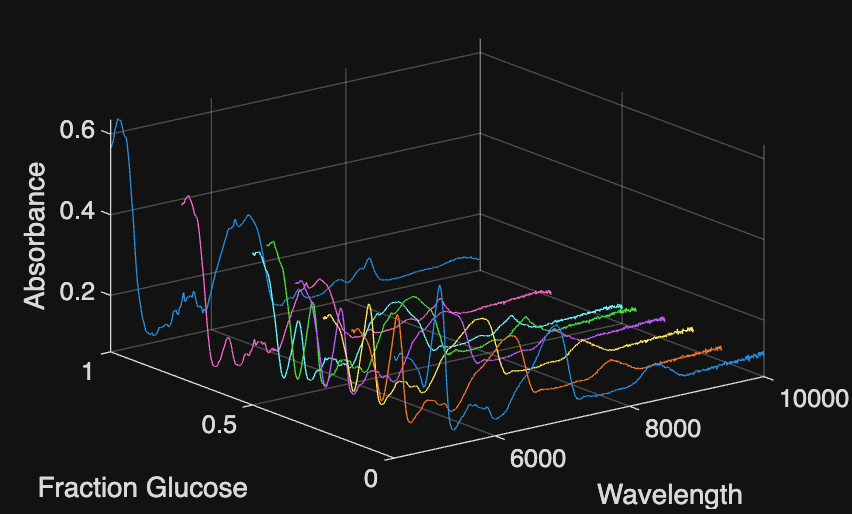

data = readmatrix("mean_data.csv");

waves = data(1, 2:end); 
percentages = data(2:end, 1);
spectra = data(2:end, 2:end);
[~, h] = sort(percentages);

figure
hold on
for i = 1:length(percentages)
    plot3( ...
        waves, ...
        percentages(h(i)) * ones(size(waves)), ...
        spectra(h(i),:) ...
    )
end
xlabel('Wavelength')
ylabel('Fraction Glucose')
zlabel('Absorbance')
grid on
axis tight
view(3)

hold off

X = spectra;
y = percentages;
[n,p] = size(X);
[Xloadings,Yloadings,Xscores,Yscores,betaPLS10,PLSPctVar] = plsregress(X,y,7);

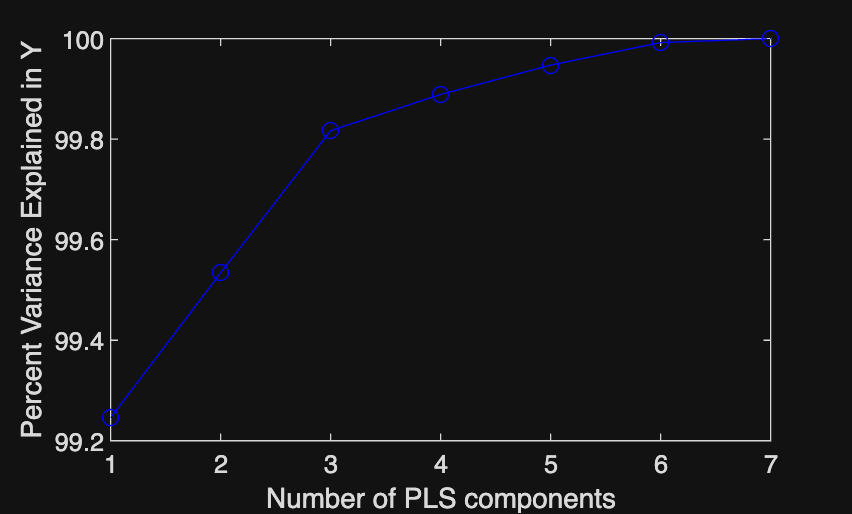

plot(1:7,cumsum(100*PLSPctVar(2,:)),'-bo');
xlabel('Number of PLS components');
ylabel('Percent Variance Explained in Y');

[Xloadings,Yloadings,Xscores,Yscores,betaPLS] = plsregress(X,y,3);
yfitPLS = [ones(n,1) X]*betaPLS;

[PCALoadings,PCAScores,PCAVar] = pca(X,'Economy',false);
betaPCR = regress(y-mean(y), PCAScores(:,1:2));
yfitPCR = [ones(n,1) X]*betaPCR;

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Related documentation

plot(y,yfitPLS,'bo',y,yfitPCR,'r^');

Unrecognized function or variable 'yfitPCR'.

xlabel('Observed Response');
ylabel('Fitted Response');
legend({'PLSR with 2 Components' 'PCR with 2 Components'},  ...
	'location','NW');

TSS = sum((y-mean(y)).^2);
RSS_PLS = sum((y-yfitPLS).^2);
rsquaredPLS = 1 - RSS_PLS/TSS

RSS_PCR = sum((y-yfitPCR).^2);
rsquaredPCR = 1 - RSS_PCR/TSS

plot3(Xscores(:,1),Xscores(:,2),y-mean(y),'bo');
legend('PLSR');
grid on; view(-30,30);

plot3(PCAScores(:,1),PCAScores(:,2),y-mean(y),'r^');
legend('PCR');
grid on; view(-30,30);

plot(1:10,100*cumsum(PLSPctVar(1,:)),'b-o',1:10,  ...
	100*cumsum(PCAVar(1:10))/sum(PCAVar(1:10)),'r-^');
xlabel('Number of Principal Components');
ylabel('Percent Variance Explained in X');
legend({'PLSR' 'PCR'},'location','SE');

yfitPLS10 = [ones(n,1) X]*betaPLS10;
betaPCR10 = regress(y-mean(y), PCAScores(:,1:10));
betaPCR10 = PCALoadings(:,1:10)*betaPCR10;
betaPCR10 = [mean(y) - mean(X)*betaPCR10; betaPCR10];
yfitPCR10 = [ones(n,1) X]*betaPCR10;
plot(y,yfitPLS10,'bo',y,yfitPCR10,'r^');
xlabel('Observed Response');
ylabel('Fitted Response');
legend({'PLSR with 10 components' 'PCR with 10 Components'},  ...
	'location','NW');

[Xl,Yl,Xs,Ys,beta,pctVar,PLSmsep] = plsregress(X,y,10,'CV',10);

PCRmsep = sum(crossval(@pcrsse,X,y,'KFold',10),1) / n;

plot(0:10,PLSmsep(2,:),'b-o',0:10,PCRmsep,'r-^');
xlabel('Number of components');
ylabel('Estimated Mean Squared Prediction Error');
legend({'PLSR' 'PCR'},'location','NE');

[Xl,Yl,Xs,Ys,beta,pctVar,mse,stats] = plsregress(X,y,3);
plot(1:401,stats.W,'-');
xlabel('Variable');
ylabel('PLS Weight');
legend({'1st Component' '2nd Component' '3rd Component'},  ...
	'location','NW');

plot(1:401,PCALoadings(:,1:4),'-');
xlabel('Variable');
ylabel('PCA Loading');
legend({'1st Component' '2nd Component' '3rd Component'  ...
	'4th Component'},'location','NW');